clear all;
close all;

m1 = 2500; %kg
m2 = 320; %kg
k1 = 80000; %N/m
k2 = 500000; %N/m
b1 = 350; % Ns/m
b2 = 15020; %Ns/m


%State space
A=[0   0   1   0
   0   0   0   1
   -k1/m1    k1/m1          -b1/m1    b1/m1
   k1/m2     -k1/m2-k2/m2    b1/m2    -b1/m2];

B=[0       0
   0       0
   1/m1    0
  -1/m2    k2/m2];

C=[1 -1 0 0];
D=[0 0];
sys=ss(A,B,C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3     -32      32   -0.14    0.14
   x4     250   -1812   1.094  -1.094
 
  B = 
              u1         u2
   x1          0          0
   x2          0          0
   x3     0.0004          0
   x4  -0.003125       1562
 
  C = 
       x1  x2  x3  x4
   y1   1  -1   0   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.




eig(A) %stabil

ans =   -0.5652 +42.6209i
  -0.5652 -42.6209i
  -0.0516 + 5.2457i
  -0.0516 - 5.2457i


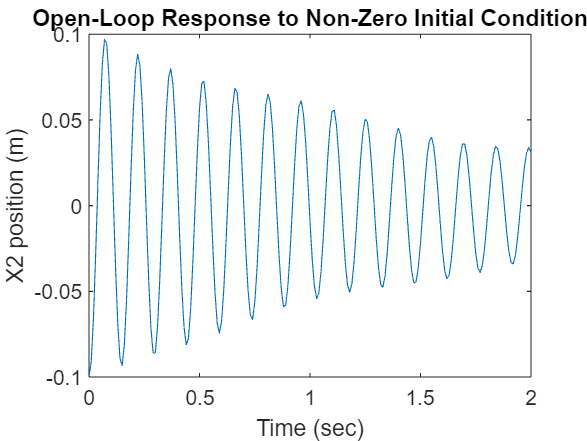


rank(ctrb(sys)); %teljesen szabályozható rangja egyenlő az állapotok számával
rank(obsv(sys)); %teljesen megfigyelhető

t = 0:0.01:2;
u = zeros(2,length(t));
x0 = [0 0.1 0 0];
[y,t,x] = lsim(sys,u,t,x0);
plot(t,y)
title('Open-Loop Response to Non-Zero Initial Condition')
xlabel('Time (sec)')
ylabel('X2 position (m)')


p1 = -20 + 10i;
p2 = -20 - 10i;
p3 = -30;
p4 = -40;

k = place(A,B,[p1 p2 p3 p4]);
sys_cl = ss(A-B*k,B,C,0);

[num,den] = ss2tf(A,B,C,D,2)

num = 1.0e+03 *

         0         0   -1.5625   -0.0000   -0.0000


den = 1.0e+04 *

    0.0001    0.0001    0.1844    0.0219    5.0000


G = tf(num,den)

G =
 
      -1563 s^2 - 2.496e-12 s - 1.262e-11
  --------------------------------------------
  s^4 + 1.234 s^3 + 1844 s^2 + 218.8 s + 50000
 
Continuous-time transfer function.



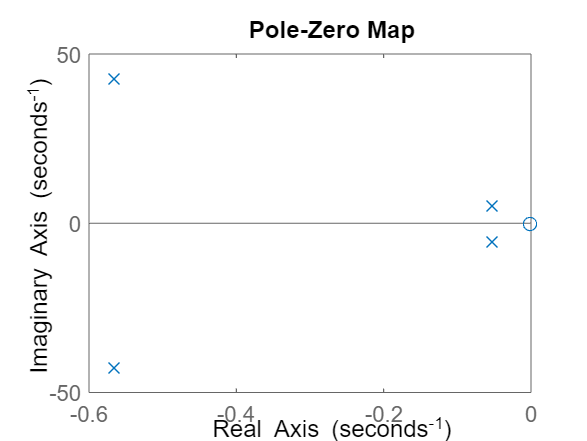

pzmap(G)

rlocus(G)
% axis([-30 30 -50 50])
z=-log(0.05)/sqrt(pi^2+(log(0.05)^2))

z = 0.6901

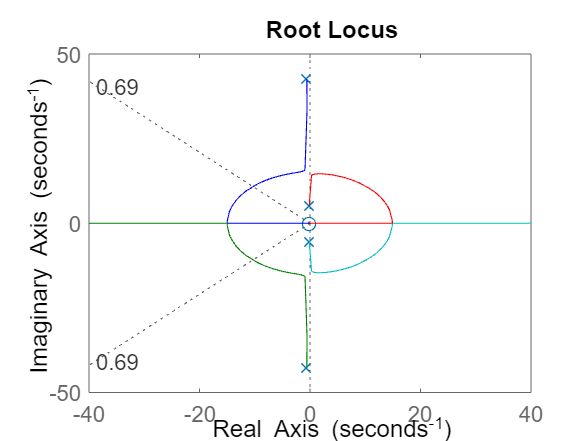

sgrid(z,0)


[num,den] = ss2tf(A-B*k,B,C,D,2)

num = 1.0e+05 *

         0         0   -0.0156   -0.6820   -5.5452


den = 1.0e+05 *

    0.0000    0.0011    0.0450    0.8300    6.0000


G = tf(num,den)

G =
 
       -1562 s^2 - 6.82e04 s - 5.545e05
  ------------------------------------------
  s^4 + 110 s^3 + 4500 s^2 + 8.3e04 s + 6e05
 
Continuous-time transfer function.



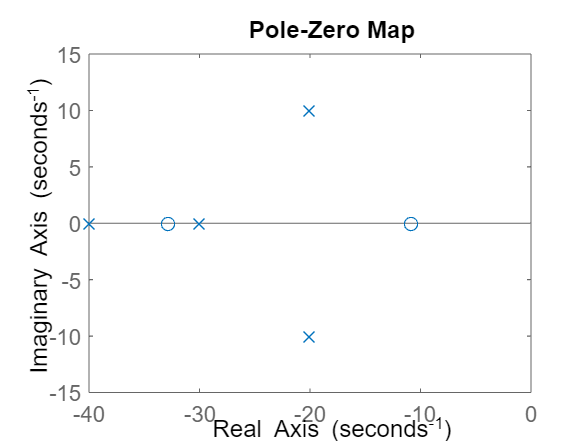

pzmap(G)

rlocus(G)
% axis([-30 30 -50 50])
z=-log(0.05)/sqrt(pi^2+(log(0.05)^2))

z = 0.6901

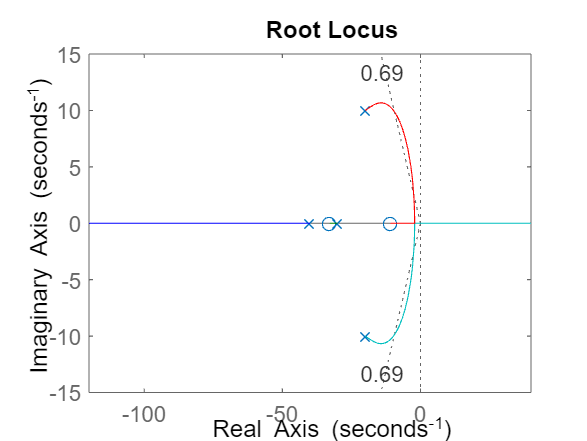

sgrid(z,0)

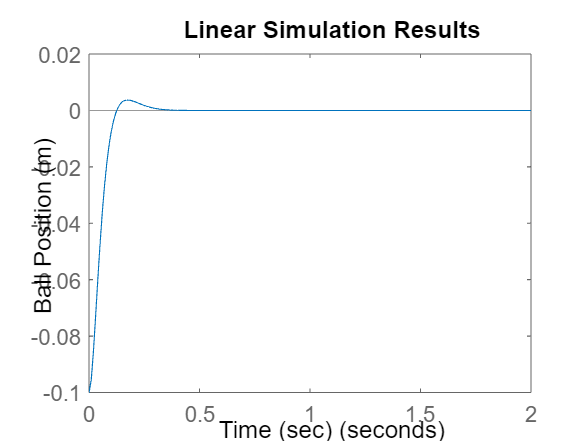




lsim(sys_cl,u,t,x0);
xlabel('Time (sec)')
ylabel('Ball Position (m)')